运行任何示例前必须先载入图像

Image=imread('工具箱图像.png');
%尝试使用GPU
try
	Image=gpuArray(Image);
catch
end
%扩大图像规模，因为较小的图像体现不出算法的优势
Image=repmat(Image,1,1,20);
NumChannels=size(Image,3);

# NormXCorr2

批量normxcorr2运算，内置函数报错，本函数支持：

tic
XCorrs=ImageProcessing.NormXCorr2(Image,permute(Image,[1 2 4 3]));
toc

历时 0.292612 秒。


tic
Builtin=zeros(size(XCorrs));
for C1=1:NumChannels
	for C2=1:NumChannels
		Builtin(:,:,C2,C1)=normxcorr2(Image(:,:,C2),Image(:,:,C1));
	end
end
toc

历时 0.857843 秒。


ErrorRatio=max(abs(XCorrs-Builtin),[],'all')/mean2(Builtin)

ErrorRatio =

     0



CPU：由于内置fft2对2维和多维数组算法实现不同，计算结果会和内置有少许误差：

GPU：无误差

对大批量图像处理任务，本函数显著优于使用循环的内置方案，无论CPU还是GPU

# Dct2

批量DCT2变换，内置函数报错，本函数支持：

tic
ImageDct2=ImageProcessing.Dct2(Image);
toc

历时 0.004484 秒。


比较内置算法

%内置dct2不支持GPU
CpuImage=gather(Image);
tic
Builtin=zeros(size(ImageDct2));
for C=1:NumChannels
	Builtin(:,:,C)=dct2(CpuImage(:,:,C));
end
toc

历时 0.042146 秒。


ErrorRatio=max(abs(ImageDct2-Builtin),[],'all')/mean2(Builtin)

ErrorRatio =

   2.1902e-12



GPU：和内置函数有少许误差，因为内置函数只能使用CPU

CPU：无误差

对大批量图像处理任务，本函数显著优于使用循环的内置方案，无论CPU还是GPU

# IDct2

Dct2的逆

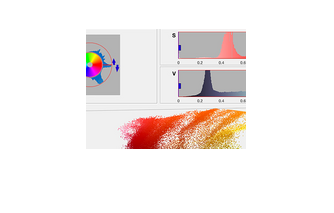

ImageIDct2=ImageProcessing.IDct2(ImageDct2);
imshow(uint8(ImageIDct2(:,:,1:3)));